syms Y
syms x(t) y(t)

delta=(0*pi/180)*cos(t)

$$delta = 0$$

f=1/10

f = 0.1000

% thrust= 300*sign(sin(2*pi*t*f));
roll=(45*pi/180)*exp(-t/6)

$$roll = \frac{\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{4}$$

thrust = 400*exp(-0.1/t)

$$thrust = 400\,{\mathrm{e}}^{-\frac{1}{10\,t}}$$

sideslipangf=0*pi/180

sideslipangf = 0

sideslipangr=0*pi/180

sideslipangr = 0


h=0.42

h = 0.4200

b=0.69319

b = 0.6932

p=0.71272+b

p = 1.4059



epsilon=0.43; %steering head angle 
daero=0.28; %aero damping coeff
ksr=92000;ksf=84400; % lateral stiffnesses of tires
Rr=0.317;Rf=0.292; % rolling radius rear and front
tr=0.097;tf=0.062; % radius of cross section rear and front
Ir=0.66;If=0.47; % Moment of inertia tires
g=9.8;
Ma=223; % rear frame mass including rider
Mb=10.0; % swingarm mass 
Mc=7.0; % front unsprung mass
Md=16.2; % rear wheel mass
Mg=12.0; % front wheel mass
Mf=8.75; % steering column mass
M = Ma+Mb+Mc+Md+Mf+Mg;

frontWcamber = asin(cos(delta)*sin(roll) + cos(roll)*sin(delta)*sin(epsilon))

$$frontWcamber = \mathrm{asin}\left(\sin\left(\frac{\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{4}\right)\right)$$

kinsteeringang = atan((sin(delta)*cos(epsilon))/(cos(roll)*cos(delta) - sin(delta)*sin(roll)*sin(epsilon)))

$$kinsteeringang = 0$$


Nr = M*g*(p-b)/p  + thrust*h/p

$$Nr = \frac{378302368699121664\,{\mathrm{e}}^{-\frac{1}{10\,t}}}{3165827876058227}+\frac{3025650034007677}{2199023255552}$$

Nf = M*g*b/p  - thrust*h/p

$$Nf = \frac{1471370487059281}{1099511627776}-\frac{378302368699121664\,{\mathrm{e}}^{-\frac{1}{10\,t}}}{3165827876058227}$$


Ds=1.1;
Bl=7;
Cl=1.3;
El=-0.3;
kl = Ds*Cl*Bl;
Bp=0.714;
Cp=1.4;
Ep=-2;
kp = Ds*Cp*Bp;

latforcer = Ds*Nr*(sin(Cl*atan(Bl*sideslipangr - El*(Bl*sideslipangr-atan(Bl*sideslipangr)))) + sin(Cp*atan(Bp*roll - Ep*(Bp*roll-atan(Bp*roll)))))

$$latforcer = -\sin\left(\frac{7\,\mathrm{atan}\left(2\,\mathrm{atan}\left(\frac{357\,\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{2000}\right)-\frac{1071\,\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{2000}\right)}{5}\right)\,\left(\frac{2080663027845169152\,{\mathrm{e}}^{-\frac{1}{10\,t}}}{15829139380291135}+\frac{33282150374084447}{21990232555520}\right)$$

% latforcer = (kl*sideslipangr + kp*roll)*Nr;
latforcef = Ds*Nf*(sin(Cl*atan(Bl*sideslipangf - El*(Bl*sideslipangf-atan(Bl*sideslipangf)))) + sin(Cp*atan(Bp*frontWcamber - Ep*(Bp*frontWcamber-atan(Bp*frontWcamber)))))

$$latforcef = \sin\left(\frac{7\,\mathrm{atan}\left(2\,\mathrm{atan}\left(\frac{357\,\mathrm{asin}\left(\sin\left(\frac{\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{4}\right)\right)}{500}\right)-\frac{1071\,\mathrm{asin}\left(\sin\left(\frac{\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{4}\right)\right)}{500}\right)}{5}\right)\,\left(\frac{2080663027845169152\,{\mathrm{e}}^{-\frac{1}{10\,t}}}{15829139380291135}-\frac{16185075357652091}{10995116277760}\right)$$

% latforcef = (kl*sideslipangr + kp*roll)*Nf;

gamma=acos((diff(x,t))/(sqrt((diff(x,t))^2 + (diff(y,t))^2)));
% gamma=atan(diff(y,t)/diff(x,t));
alpha=gamma-sideslipangr;

Fthrust = [cos(alpha);sin(alpha)]*thrust;
Flr = [-sin(alpha);cos(alpha)]*latforcer;
Flf = [-sin(alpha+kinsteeringang);cos(alpha+kinsteeringang)]*latforcef;
F = Fthrust+Flr+Flf;
W = [x y]*F;

% dissipative functions
    % aerodynamic drag
Daero = 0.5*daero*((diff(x,t))^2 + (diff(y,t))^2);
Diss = Daero;

KE = 0.5*M*((diff(x,t))^2 + (diff(y,t))^2);
L = KE;
eqn1 = diff(diff(L,diff(x,t)),t) - diff(L,x) + diff(Diss,diff(x,t)) == diff(W,x);
eqn2 = diff(diff(L,diff(y,t)),t) - diff(L,y) + diff(Diss,diff(y,t)) == diff(W,y);
eqns = [eqn1;eqn2]

$$eqns(t) = \begin{array}{l} \left(\begin{array}{c} \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}x\left(t\right)}{25}=\sigma_{1}\,\sigma_{5}\,\sigma_{2}+\frac{400\,\sigma_{8}\,\frac{\partial }{\partial t}x\left(t\right)}{\sqrt{\sigma_{6}}}-\sigma_{3}\,\sigma_{4}\,\sigma_{2}\\ \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}y\left(t\right)}{25}=400\,\sigma_{8}\,\sigma_{2}+\frac{\sigma_{3}\,\sigma_{4}\,\frac{\partial }{\partial t}x\left(t\right)}{\sqrt{\sigma_{6}}}-\frac{\sigma_{1}\,\sigma_{5}\,\frac{\partial }{\partial t}x\left(t\right)}{\sqrt{\sigma_{6}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{7\,\mathrm{atan}\left(2\,\mathrm{atan}\left(\frac{357\,\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{2000}\right)-\frac{1071\,\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{2000}\right)}{5}\right)\\ \sigma_{2}=\sqrt{1-\frac{\sigma_{9}}{\sigma_{6}}}\\ \sigma_{3}=\sin\left(\frac{7\,\mathrm{atan}\left(2\,\mathrm{atan}\left(\frac{357\,\sigma_{7}}{500}\right)-\frac{1071\,\sigma_{7}}{500}\right)}{5}\right)\\ \sigma_{4}=\frac{2080663027845169152\,\sigma_{8}}{15829139380291135}-\frac{16185075357652091}{10995116277760}\\ \sigma_{5}=\frac{2080663027845169152\,\sigma_{8}}{15829139380291135}+\frac{33282150374084447}{21990232555520}\\ \sigma_{6}=\sigma_{9}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\\ \sigma_{7}=\mathrm{asin}\left(\sin\left(\frac{\pi \,{\mathrm{e}}^{-\frac{t}{6}}}{4}\right)\right)\\ \sigma_{8}={\mathrm{e}}^{-\frac{1}{10\,t}}\\ \sigma_{9}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2} \end{array}$$


[VF,Subs] = odeToVectorField(eqns);
odefcn = matlabFunction(VF, 'Vars',{t,Y});
[X,Y] = ode45(odefcn, [0 15], [0 0 0 70/3.6]);
Subs

$$Subs = \left(\begin{array}{c} y\\ \mathrm{Dy}\\ x\\ \mathrm{Dx} \end{array}\right)$$

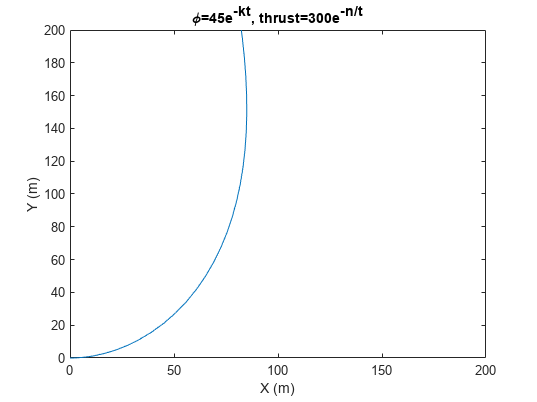

plot(Y(:,3),Y(:,1))
xlabel('X (m)')
ylabel('Y (m)')
% title('\phi=60\circ \delta=0\circ S=0N')
title('\phi=45e^{-kt}, thrust=300e^{-n/t}')
axis([0 200 0 200])

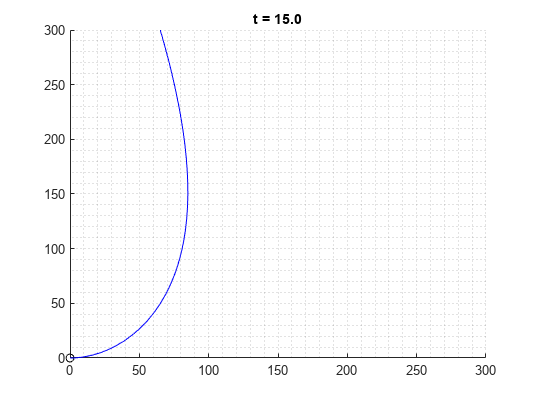


ycoord = Y(:,1);
xcoord = Y(:,3);

% ANIMATION
figure
hold on
grid minor 
axis([0 300 0 300])
% Plotting with no color to set axis limits
plot(xcoord,ycoord,'Color','none');
% Plotting the first iteration
plot(0,0,'ko')
p1 = plot(xcoord(1),ycoord(1),'b');
m1 = scatter(xcoord(1),ycoord(1),'filled','b');
% Iterating through the length of the time array
for k = 1:length(Y(:,1))
%     Updating the line
    p1.XData = xcoord(1:k);
    p1.YData = ycoord(1:k);
%     Updating the point
    m1.XData = xcoord(k); 
    m1.YData = ycoord(k);
    title(sprintf('t = %.1f', X(k)) );
%     Delay
    pause(0.1)
end